## Inertia Matrix using DH generalized coordinate

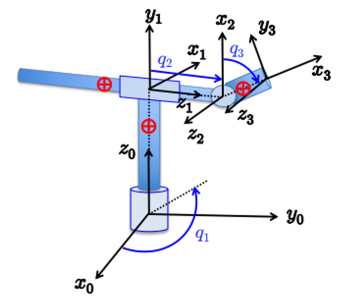

syms d1 d2 d3 q1 q2 q3 l2 l1 l3 positive
syms dq1 dq2 dq3 m1 m2 m3 positive
syms I1_xx I1_yy I1_zz I2_xx I2_yy I2_zz I3_xx I3_yy I3_zz I3 I2 

% Joint 1
T1 = 0.5*I1_yy*(dq1^2)

$$T1 = \frac{I_{1,\mathrm{yy}}\,{{\mathrm{dq}}_{1}}^{2}}{2}$$


% Joint 2
p2 = [(q2-d2)*cos(q1); (q2-d2)*sin(q1); 0]

$$p2 = \left(\begin{array}{c} -\cos\left(q_{1}\right)\,\left(d_{2}-q_{2}\right)\\ -\sin\left(q_{1}\right)\,\left(d_{2}-q_{2}\right)\\ 0 \end{array}\right)$$

vx2 = diff(p2(1), q1)*dq1 + diff(p2(1), q2)*dq2 + diff(p2(1), q3)*dq3;
vy2 = diff(p2(2), q1)*dq1 + diff(p2(2), q2)*dq2 + diff(p2(2), q3)*dq3;
v2 = [vx2; vy2; 0;]

$$v2 = \left(\begin{array}{c} {\mathrm{dq}}_{2}\,\cos\left(q_{1}\right)+{\mathrm{dq}}_{1}\,\sin\left(q_{1}\right)\,\left(d_{2}-q_{2}\right)\\ {\mathrm{dq}}_{2}\,\sin\left(q_{1}\right)-{\mathrm{dq}}_{1}\,\cos\left(q_{1}\right)\,\left(d_{2}-q_{2}\right)\\ 0 \end{array}\right)$$

T2_tr = 0.5*((simplify(norm(v2)^2,steps=100)))*m2;
T2_rot = 0.5*(dq1^2)*I2;
T2 = simplify(T2_tr+T2_rot, steps=100)

$$T2 = \frac{I_{2}\,{{\mathrm{dq}}_{1}}^{2}}{2}+\frac{m_{2}\,\left({d_{2}}^{2}\,{{\mathrm{dq}}_{1}}^{2}-2\,d_{2}\,{{\mathrm{dq}}_{1}}^{2}\,q_{2}+{{\mathrm{dq}}_{1}}^{2}\,{q_{2}}^{2}+{{\mathrm{dq}}_{2}}^{2}\right)}{2}$$


% Joint 3 
p3 = [(-d3*sin(q3)+q2)*sin(q1); -(-d3*sin(q3)+q2)*cos(q1); l1+d3*cos(q3);];
vx3 = diff(p3(1), q1)*dq1 + diff(p3(1), q2)*dq2 + diff(p3(1), q3)*dq3;
vy3 = diff(p3(2), q1)*dq1 + diff(p3(2), q2)*dq2 + diff(p3(2), q3)*dq3;
vz3 = diff(p3(3), q1)*dq1 + diff(p3(3), q2)*dq2 + diff(p3(3), q3)*dq3;
% v3 = [vx2; vy2; vz3;]
v3 = jacobian(p3, [q1 q2 q3]) * [dq1; dq2; dq3]

$$v3 = \left(\begin{array}{c} {\mathrm{dq}}_{2}\,\sin\left(q_{1}\right)+{\mathrm{dq}}_{1}\,\cos\left(q_{1}\right)\,\left(q_{2}-d_{3}\,\sin\left(q_{3}\right)\right)-d_{3}\,{\mathrm{dq}}_{3}\,\cos\left(q_{3}\right)\,\sin\left(q_{1}\right)\\ {\mathrm{dq}}_{1}\,\sin\left(q_{1}\right)\,\left(q_{2}-d_{3}\,\sin\left(q_{3}\right)\right)-{\mathrm{dq}}_{2}\,\cos\left(q_{1}\right)+d_{3}\,{\mathrm{dq}}_{3}\,\cos\left(q_{1}\right)\,\cos\left(q_{3}\right)\\ -d_{3}\,{\mathrm{dq}}_{3}\,\sin\left(q_{3}\right) \end{array}\right)$$

omega3 = [cos(q3)*dq1; -sin(q3)*dq1; dq3;];

T3 = 0.5*m3*((simplify(norm(v3)^2,steps=100))) + 0.5*I3*((simplify(norm(omega3)^2,steps=100)))

$$T3 = \frac{m_{3}\,\left(-{d_{3}}^{2}\,{{\mathrm{dq}}_{1}}^{2}\,{\cos\left(q_{3}\right)}^{2}+{d_{3}}^{2}\,{{\mathrm{dq}}_{1}}^{2}+{d_{3}}^{2}\,{{\mathrm{dq}}_{3}}^{2}-2\,\sin\left(q_{3}\right)\,d_{3}\,{{\mathrm{dq}}_{1}}^{2}\,q_{2}-2\,d_{3}\,{\mathrm{dq}}_{2}\,{\mathrm{dq}}_{3}\,\cos\left(q_{3}\right)+{{\mathrm{dq}}_{1}}^{2}\,{q_{2}}^{2}+{{\mathrm{dq}}_{2}}^{2}\right)}{2}+\frac{I_{3}\,\left({{\mathrm{dq}}_{1}}^{2}+{{\mathrm{dq}}_{3}}^{2}\right)}{2}$$


% Total Kinetic Energy
T = T1+T2+T3

$$T = \begin{array}{l} \frac{m_{3}\,\left(-{d_{3}}^{2}\,{{\mathrm{dq}}_{1}}^{2}\,{\cos\left(q_{3}\right)}^{2}+{d_{3}}^{2}\,{{\mathrm{dq}}_{1}}^{2}+{d_{3}}^{2}\,{{\mathrm{dq}}_{3}}^{2}-2\,\sin\left(q_{3}\right)\,d_{3}\,{{\mathrm{dq}}_{1}}^{2}\,q_{2}-2\,d_{3}\,{\mathrm{dq}}_{2}\,{\mathrm{dq}}_{3}\,\cos\left(q_{3}\right)+\sigma_{1}+{{\mathrm{dq}}_{2}}^{2}\right)}{2}+\frac{I_{2}\,{{\mathrm{dq}}_{1}}^{2}}{2}+\frac{I_{1,\mathrm{yy}}\,{{\mathrm{dq}}_{1}}^{2}}{2}+\frac{I_{3}\,\left({{\mathrm{dq}}_{1}}^{2}+{{\mathrm{dq}}_{3}}^{2}\right)}{2}+\frac{m_{2}\,\left({d_{2}}^{2}\,{{\mathrm{dq}}_{1}}^{2}-2\,d_{2}\,{{\mathrm{dq}}_{1}}^{2}\,q_{2}+\sigma_{1}+{{\mathrm{dq}}_{2}}^{2}\right)}{2}\\ \mathrm{where}\\ \sigma_{1}={{\mathrm{dq}}_{1}}^{2}\,{q_{2}}^{2} \end{array}$$


% Inertia Matrix
M11 = diff(diff(T, dq1), dq1);
M12 = diff(diff(T, dq1), dq2);
M13 = diff(diff(T, dq1), dq3);

M21 = diff(diff(T, dq2), dq1);
M22 = diff(diff(T, dq2), dq2);
M23 = diff(diff(T, dq2), dq3);

M31 = diff(diff(T, dq3), dq1);
M32 = diff(diff(T, dq3), dq2);
M33 = diff(diff(T, dq3), dq3);

M = [M11, M12, M13;
     M21, M22, M23;
     M31, M32, M33];

M = simplify(M);

disp('The inertia matrix M(q) is:');

The inertia matrix M(q) is:


disp(M);

$$\left(\begin{array}{ccc} I_{2}+I_{3}+I_{1,\mathrm{yy}}+{d_{2}}^{2}\,m_{2}+m_{2}\,{q_{2}}^{2}+m_{3}\,{q_{2}}^{2}-2\,d_{2}\,m_{2}\,q_{2}+{d_{3}}^{2}\,m_{3}\,{\sin\left(q_{3}\right)}^{2}-2\,d_{3}\,m_{3}\,q_{2}\,\sin\left(q_{3}\right) & 0 & 0\\ 0 & m_{2}+m_{3} & -d_{3}\,m_{3}\,\cos\left(q_{3}\right)\\ 0 & -d_{3}\,m_{3}\,\cos\left(q_{3}\right) & m_{3}\,{d_{3}}^{2}+I_{3} \end{array}\right)$$